# **Exercício 3 - cap 7**

**Discente: **Raphael Ramos da Silva

Utilizando os laboratórios disponibilizados no [**link**](http://utam.gg.utah.edu/Classes/ML/LAB1/Chapter.Book.SVM/lab.html):

- Compare a filtragem de ruídos de migração usando FCNN e SVM com Kernel RBF.

- Envie os resultados com devidas análises em um notebook (Python ou Matlab).

**Try to train the model with an unbalanced training set. For examples, we have 50 artifacts points and 3 reflector points in the training set.**

Alterando as variáveis n_refl e n_arti no compapre_main.m para

n_refl=3;n_arti=50;

Temos os seguintes resultados de classificação dos pontos

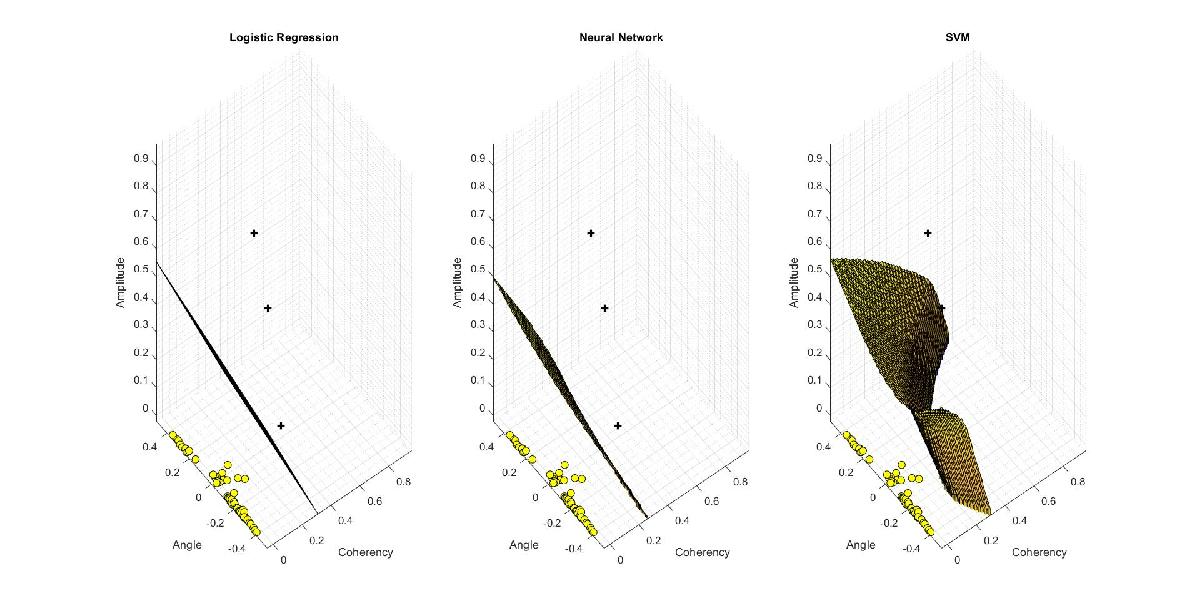

E os resultados das migrações filtradas para cada um dos métodos utilizados

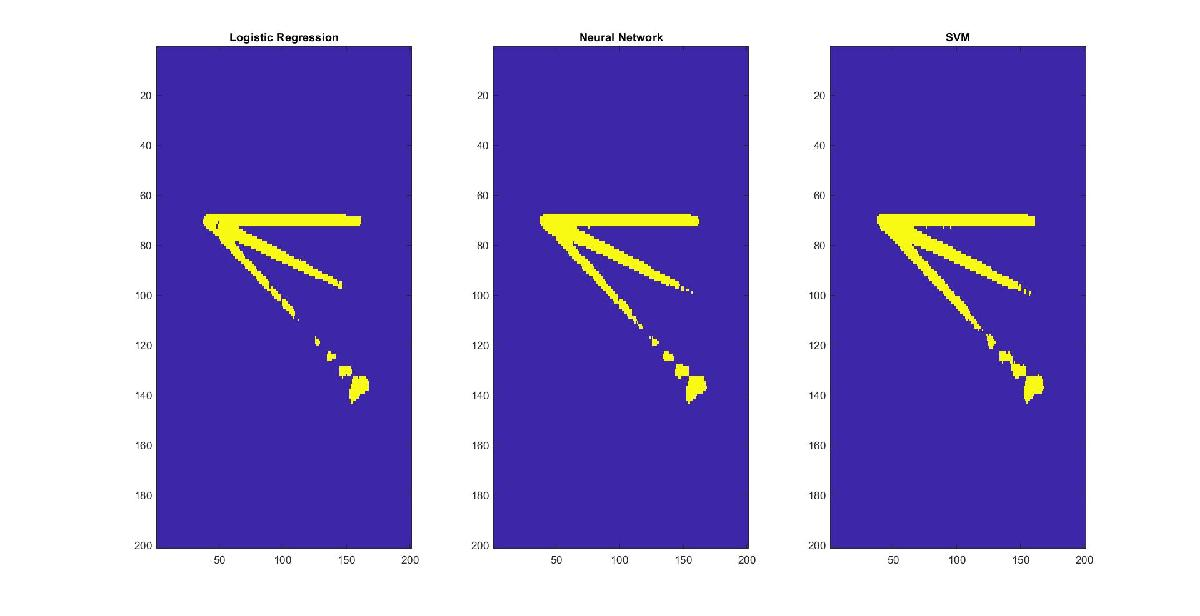

No resultado da migração dos três métodos, a máscara amarela manteve a geometria linear dos três refletores. Além disso, os arcos de difração foram removidos com sucesso. Mas, um aspecto que deixou a desejar nos três métodos foi a permanência do *aliasing* no terceiro evento.

**Modify the program as follows: (1) For each image point in the migration image, open a local window with size of winx by winz around this image point. (2) Unroll this local image to the size of 1 by winx*winz and saved as one example in the training set. so in this case, the dimension of input features are winx by winz).**

O script `comapre_main.m` calcula 3 atributos por ponto (cohe, angl, engy) e cada exemplo de treinamento vira algo como [cohe, angl, engy].

Agora, pelo o que é solicitado no enunciado, para cada ponto da imagem de migração, deve-se:

 1. pegar uma janela local centrada nesse ponto, com tamanho winx × winz;

 2. “desenrolar” essa janela em um vetor de tamanho 1 × (winx*winz);

 3. usar esse vetor como um exemplo do treinamento.

Em outras palavras, cada amostra deixa de ser 3 números e passa a ser a assinatura completa da vizinhança ao redor do ponto. Assim, a matriz X teria winx*winz colunas, e não 3.

% o script comapre_janela_main.m implementa esta versao

**Train the model and compare the predicted classes to the actual classes.**